% Load the selected features from the Excel file
selected_features = readmatrix('selected_eeg_features6.csv');

% Assuming you have labels for each epoch in a vector labels
% Ensure that the length of the labels vector matches the number of rows in selected_features
num_epochs_total = size(selected_features, 1);

% Replace this with your actual labels data
labels = randi([0, 1], num_epochs_total, 1); % Random labels for demonstration

% Separate the features and the channel indices
channel_indices = selected_features(:, 1);
feature_data = selected_features(:, 2:end);

% Split the data into training and testing sets (80% training, 20% testing)
cv = cvpartition(labels, 'HoldOut', 0.2);
trainIdx = training(cv);
testIdx = test(cv);

% Training data
X_train = feature_data(trainIdx, :);
y_train = labels(trainIdx);

% Testing data
X_test = feature_data(testIdx, :);
y_test = labels(testIdx);

% Train the KNN classifier with Minkowski distance metric
k = 5; % Number of neighbors, you can tune this
KNNModel = fitcknn(X_train, y_train, 'NumNeighbors', k, 'Distance', 'minkowski', 'Standardize', 1);

% Predict the labels for the test set
y_pred = predict(KNNModel, X_test);

% Evaluate the classifier performance
accuracy = sum(y_pred == y_test) / length(y_test);
confMat = confusionmat(y_test, y_pred);

fprintf('Model Accuracy: %.2f%%\n', accuracy * 100);

Model Accuracy: 49.41%


disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

    46    43
    43    38


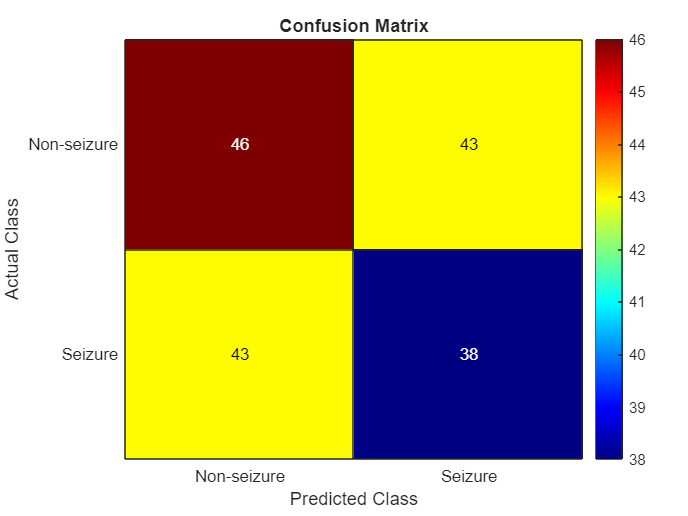


% Visualize the confusion matrix
figure;
heatmap({'Non-seizure', 'Seizure'}, {'Non-seizure', 'Seizure'}, confMat, ...
        'Colormap', jet, 'ColorbarVisible', 'on');
title('Confusion Matrix');
xlabel('Predicted Class');
ylabel('Actual Class');


% Save the trained model
save('KNNModel6.mat', 'KNNModel');
disp('KNN model saved as KNNModel.mat');

KNN model saved as KNNModel.mat
